# Consumption Rates Project

## Background

This script is designed to take a Google sheet I made "Average Alcohol Consumption Rates" and generate insightful figures from its data. The data are variables measured by myself and others (according to standardized procedures within the company). The data include most of the accessible information regarding alcohol-related behaviors among guests at catered events (weddings, memorials, bar mitzvahs, tailgates etc.). Of primary importance to the bar department of this company is the prediction of how much alcohol to bring to an event, knowing relatively few predictor variables. What we do know includes guest count and bartime, which I hypothesize are, together, sufficiently powerful predictors to functionally solve the problem. However, the company caters (and provides bars for) a wide variety of events, some happening in the late morning, some providing only beer and wine. For the purposes of investigation, much of my free time has gone to pulling apart these factors and programming the following script. 

For reference, here is what a blank pull sheet looks like. This is just the frontmost page, not showing any financial calculations. The bones of this sheet are the only thing in this project that were not my creation. However, the version shown has been reprogrammed in a number of ways, not least to calculate some data explicitly, so that those data can then be referenced into the next sheet.

#### Master Bar Sheet (or "Pull Sheet")

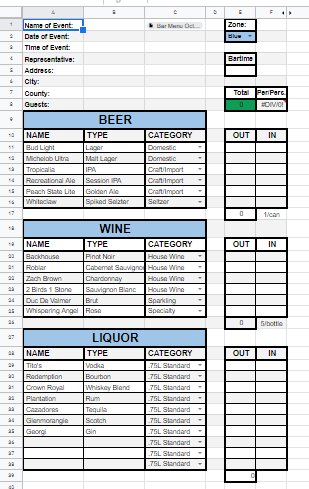

Everything below is entirely my creation.


clc; clear; close all;
cd('C:\Users\Noah3\Coding')
addpath(genpath('C:\Users\Noah3\Coding'))

DataSheet = readtable('Average Alcohol Consumption Rates 2023.xlsx', 'Range', 'A2:AW36');

table2struct(DataSheet);


Here is what that sheet looked like in Google:

#### Average Alcohol Consumption Rates

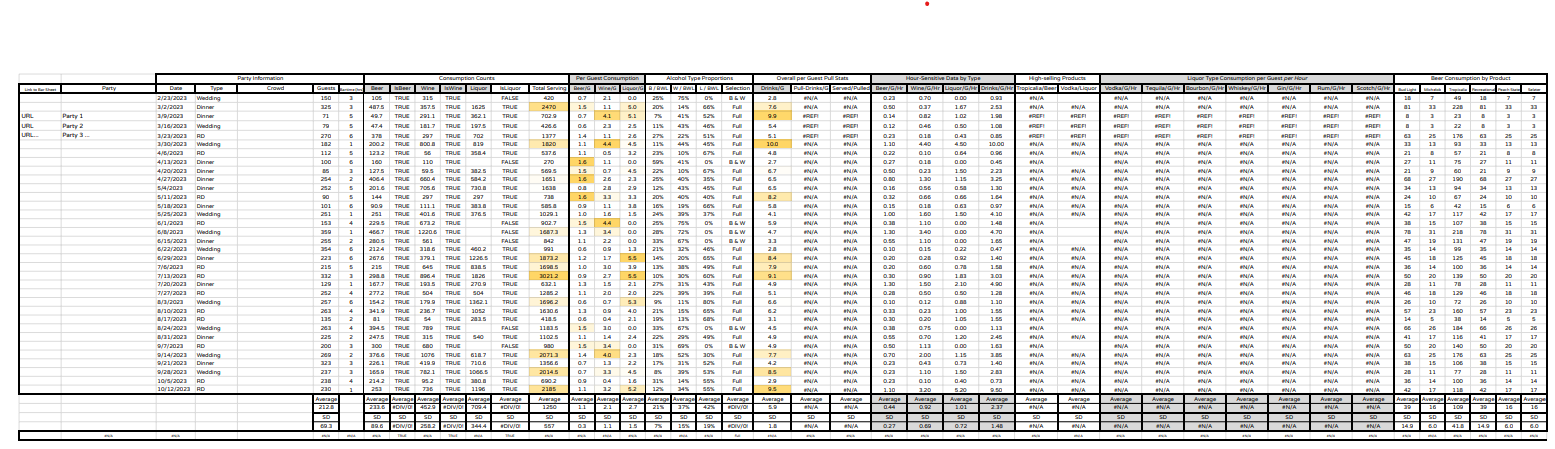

This sheet extends beyond to the right, but for our purposes the columns shown are all that are needed. This is a version of the sheet with mock data filled in. In the actual sheet, each party's official title, and the* entire row *is generated automatically by inputting the URL into the leftmost cell, corresponding to the party's pull sheet and financial report.

This Google sheet is also used to then power another, which automatically create a prediction pull sheet based on guest count, bartime (two of the main, easily accesible, known factors about a prospective event).

#### Reference Auto-Filling Bar Sheet

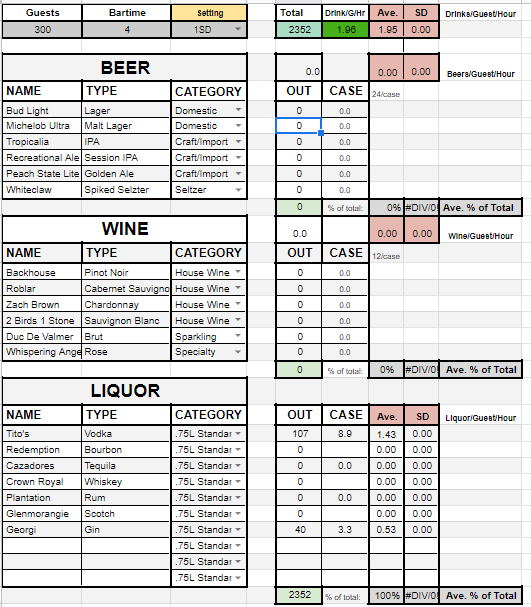

The "Setting" option allows the user to choose at what SD the sheet outputs its suggestion. For instance, when set to "Average", the sheet will suggest an amount of alcohol that is likely to be drank through entirely by 50% of parties (not very useful in and of itself). However, when set to 2SD, it outputs an amount that has about a 97.5% of not running out. (We should note for practical purposes that this by no means guarantees not running out of a particular product. To avoid this, we assume that the relative proportions are sufficiently unvarying)

Each quantity is calculated by the actual past drinking behaviors of each type of drink, as aggregated in the Average Alcohol Consumption Rates sheet. In fact, the liquor types (because it is more necessary there) are broken down by type of liquor. For example, the average historical Gin/Guest/Hour, and the standard deviation of that dataset across parties, are what are used to generate the Gin pull suggestion.

This sheet includes some cells intended for error detection (which are, otherwise, technically redundant or uninformative). For this purpose, a comparison is shown between the Prediction Sheet's "percentage of total pull as liquor" (or beer, or wine), and the historical, empirical average across parties of the percentage of total consumption as liquor. This acts as something like a failsafe, to alert the user that something might be off, such as the underlying programming having broken. When all is well, the two percentages should be plausibly similar.

Throughout all the Google sheets, calculations are frequently made to convert between ounces, milliliters, cans, servings, bottles, packs, and cases. For instance, the Auto-Filling Bar Sheet has cells that allow the selection of bottle size of the respective liquor, which then changes how many bottles the sheet outputs to meet a certain drink count. Those drink counts are then totaled, and that number is compared, as another failsafe, against the historical, empirical, total servings per guest per hour. Multiple cells are set to change their color as the values pass certain other metrics. For instance, "1 drink per guest per total hours of bartime plus 1" is a metric used to pull alcohol quantities, and was standard before all of this was implemented. It tends to overpull by a bit, but the total servings cell is set to turn progressively more green the closer it gets to this metric. This allows the sheet to reference metrics beyond the data, and increase its reliability, particularly before sufficient data has been inputted into the Average Alcohol Consumption Rates sheet.

% Known Error Sources
% Make sure the relevant columns in the original spreadsheet are filled in for the 'Range' specified above,
% especially Drinks/G and Drinks/G/Hr.
%
% If a party lacks a type, it will break the "Breakdown by Type" section
%
% If there are no B&W parties, it will break the BW vs BWL section

## Determining Normality of the Distribution of [Drinks per Guest per Hour]

Do parties really vary in a normal distribution?

I hypothesized that the distribution of 'how much people drink' is normal--that is, most of the time people drink a particular amount (at a particular rate by the hour), with occasional instances involving less alcohol-interested folks, and others involving a group that drinks more than the norm.

An Anderson-Darling test is supposed to verify the normality of a distribution. Here I apply that test to the data of "Drinks per Guest per Hour," which was calculated for each party automatically, in the Average Alcohol Consumption Rates sheet, which itself is fed by each party's financial report sheet.

% The Anderson-Darling Test on servings per guest:

[h, p] = adtest(DataSheet.Drinks_G_Hr);

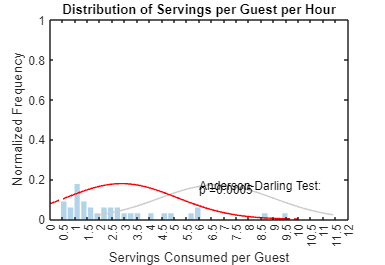

AD_Pvalue = num2str(fix(p*10000)/10000); %fixing the value multiplied by 10 and then dividing it by 10 just cuts off decimals at a certain digit


f1 = figure;
set(f1, 'Position', [546,491,471,324])


% Compute the histogram counts and bin edges

[counts, edges] = histcounts(DataSheet.Drinks_G_Hr,'Normalization', 'probability','BinWidth',.27);
bar( edges(1:end-1), counts,'FaceAlpha', .3,'LineStyle','none')


hold on % Keep that figure! Add this stuff to it.

% Calculate the mean and standard deviation of the data

ServByGuest_mu = mean(DataSheet.Drinks_G);
ServByGuest_sigma = std(DataSheet.Drinks_G);

ServByGuestPerHour_mu = mean(DataSheet.Drinks_G_Hr);
ServByGuestPerHour_sigma = std(DataSheet.Drinks_G_Hr);

% Generate x values and the probability density function (PDF) of the normal distribution

ServByGuest_x = linspace(min(DataSheet.Drinks_G), max(DataSheet.Drinks_G), 100);
ServByGuest_y = normpdf(ServByGuest_x, ServByGuest_mu, ServByGuest_sigma);

ServByGuestPerHour_x = linspace(min(DataSheet.Drinks_G_Hr), max(DataSheet.Drinks_G_Hr), 100);
ServByGuestPerHour_y = normpdf(ServByGuestPerHour_x, ServByGuestPerHour_mu, ServByGuestPerHour_sigma);


% Let's draw a full normal distribution for visual comparison

Primyer_mu = ServByGuestPerHour_mu;
Primyer_sigma = ServByGuestPerHour_sigma;
Primyer_x = 0:0.1:10;
Primyer_y = normpdf(Primyer_x, Primyer_mu, Primyer_sigma);

% This forces a normal distribution curve out of the data. Is that curve
% real? The Anderson-Darling test is how we tell. The histogram behind
% should match the hypothetical normal curve, whereupon the AD-test also
% passes. When the histogram, generated more closely from the actual layout
% of the data, matches the forceably normally represented curve, then we
% can suspect the actual data really is normally distributed.
% Then we can say that that hypothetical curve is a genuine and real summation of the data.


% Plot the normal curve on top of the histogram, with the Primyer curves
plot(ServByGuest_x, ServByGuest_y, '-','Color', [.8 .8 .8])
plot(ServByGuestPerHour_x, ServByGuestPerHour_y, '-r', Primyer_x, Primyer_y, '--r')
text(6,.15,['p =' AD_Pvalue])
text(6,.17, 'Anderson-Darling Test:')
title('Distribution of Servings per Guest per Hour')
xline(0)
yline(0)
xlabel('Servings Consumed per Guest')
ylabel('Normalized Frequency')
xticks([0:.5:15])
ylim([0 1])

## Error Measurements

% Calculate n of dataset 
n = length(DataSheet.Drinks_G_Hr);
ServByGuestPerHour_sigma = std(DataSheet.Drinks_G_Hr);
err = ServByGuestPerHour_sigma / sqrt(n);

## Graph of Consumption According to Guest Count

Having determined normality, we can say that something like a "standard deviation" (SD) is actually meaningful for the dataset. So, let's create a graph of guest count on the X, and consumption on the Y, and make (1) a regression line for that data; (2) percentage encompassing lines around that, e.g. 75% of the data between two lines (this process as I've done it here requires that the SD be real, and the data normal).

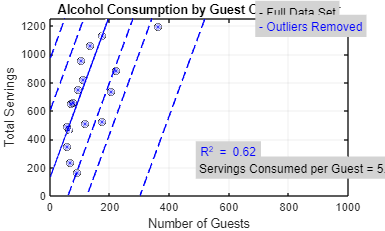

% Create a reduced data set without outliers, but keep that one

outliers = isoutlier(DataSheet.TotalServing);
% (x 900, y 828) needs adding back in
NonOutlierIndex_001 = find(DataSheet.TotalServing == 828);
outliers(NonOutlierIndex_001) = 0;

% Select the values of x that correspond to the outliers in y

Guests_outliers = DataSheet.Guests(outliers);

% Remove the outliers from y

TotalServing_clean = DataSheet.TotalServing(~outliers);

% Remove the corresponding values of x from x

Guests_clean = DataSheet.Guests(~outliers);
 

% Sort out the values for the equations to draw regression lines on full
% and on the reduced dataset.


% Cleaned Data Line

p = polyfit(  Guests_clean,  TotalServing_clean,  1); % Store in p the 'y = 0x^3 + 0x^2 + mx^1 + bx^0' equation that would fit the data. p(1) = m, p(0) = b 
xfit = linspace(min(Guests_clean), max(Guests_clean)+200, 100);
yfit = polyval(p, xfit);

% Full Data Line

p2 = polyfit(  DataSheet.Guests,  DataSheet.TotalServing,  1);
xfit2 = linspace(min(DataSheet.Guests), max(DataSheet.Guests)+200, 100);
yfit2 = polyval(p2, xfit2);


yfitAtXs = polyval(p2, Guests_clean); % Need this later for r^2

% residuals = TotalServing_clean - yfitAtXs; % Need these later for error bars
% stddev = std(residuals);



%% Consumption by guest count figure

f2 = figure;
set(f2, 'Position', [1,490,544,326])


plot(DataSheet.Guests, DataSheet.TotalServing,'ko', ... % Black circles for all events
    Guests_clean, TotalServing_clean, 'b*', ...         % Blue star at reduced set
    xfit2, yfit2, 'w', ... % Black line for the regression of full set
    xfit, yfit, 'b-')       % Blue line for the regression of reduced set
hold on
% Let's make lines corresponding to the +-1SD and +-2SD around our
% regression line. This visualizes a prediction of what consumption amount any guest count is
% 97.7% likely to drink less than. Granted, nothing is stopping everyone
% from anomalously deciding to unanimously drink one product.


RegressionExtendedLine = refline(p(1),p(2)); % Create a reference line named that, using the values of p, which give you (...5,4,3,) slope(2), y-int(1).
RegressionExtendedLine.Color = 'blue';
RegressionExtendedLine.LineWidth = 1;
TotalServing_clean_sigma = std(TotalServing_clean);

RegressionLine_1SDLess = refline(p(1),p(2)-.65*TotalServing_clean_sigma); % 50% of Data lines
RegressionLine_1SDMore = refline(p(1),p(2)+.65*TotalServing_clean_sigma);
RegressionLine_1SDLess.LineWidth = .3;
RegressionLine_1SDMore.LineWidth = .3;
RegressionLine_1SDLess.LineStyle = '--';
RegressionLine_1SDMore.LineStyle = '--';
RegressionLine_1SDLess.Color = 'blue';
RegressionLine_1SDMore.Color = 'blue';

RegressionLine_1SDLess = refline(p(1),p(2)-1.15*TotalServing_clean_sigma); % 75% of Data line
RegressionLine_1SDMore = refline(p(1),p(2)+1.15*TotalServing_clean_sigma);
RegressionLine_1SDLess.LineWidth = .3;
RegressionLine_1SDMore.LineWidth = .3;
RegressionLine_1SDLess.LineStyle = '--';
RegressionLine_1SDMore.LineStyle = '--';
RegressionLine_1SDLess.Color = 'blue';
RegressionLine_1SDMore.Color = 'blue';

RegressionLine_1SDLess = refline(p(1),p(2)-2.55*TotalServing_clean_sigma); % 99% of Data lines
RegressionLine_1SDMore = refline(p(1),p(2)+2.55*TotalServing_clean_sigma);
RegressionLine_1SDLess.LineWidth = .3;
RegressionLine_1SDMore.LineWidth = .3;
RegressionLine_1SDLess.LineStyle = '--';
RegressionLine_1SDMore.LineStyle = '--';
RegressionLine_1SDLess.Color = 'blue';
RegressionLine_1SDMore.Color = 'blue';

% Set and label up our graph now

title('Alcohol Consumption by Guest Count per Hour')
xlabel('Number of Guests');
ylabel('Total Servings');
grid('on');
set(gca, 'GridAlpha', .05)

% The reference line just matches the reduced set's regression line, but
% extends beyond the data range


% For the squaring process to work, we can't use a polyval() taking an xfit made up of an arbitrary amount of data. 
% Instead we're making a polyval() off of Guests_Clean (an x axis value) so that when we generate a yfit from it, 
% it matches the number of data points in TotalServing_Clean. Then the squaring+summing process can fold into 1 value,
% so that the final r^2 pops out a single value, as it should... Not a 1x100. 


R2 = 1 - sum((TotalServing_clean - yfitAtXs).^2)/sum((TotalServing_clean - mean(TotalServing_clean)).^2);
R2 = (fix(R2 * 100) / 100);

% Add text labels for things.

text(500, 300, ['R^2 = ' num2str(R2)],'Color','b','BackgroundColor','#D3D3D3'); % Show me that r^2
text(700, 1300, '- Full Data Set','Color','k','BackgroundColor','#D3D3D3');
text(700, 1200, '- Outliers Removed','Color','b','BackgroundColor','#D3D3D3');
text(500,200, ['Servings Consumed per Guest = ' num2str(fix(p(1) * 100) / 100)], 'Color', 'k','BackgroundColor','#D3D3D3')
xlim([0 1000]);
ylim([0 1250]);

hold off

## Plotting the Differences between Types of Events (in Servings/Guest/Hour)

#### The Normal Curves of Consumption Split by Type

Another figure that would be interesting to see is whether or not, and how, the *type* of event affects alcohol consumption. For events in the evening, such as dinner parties and wedding receptions, do people drink different amounts as a function of the type of event?

The next section takes the Average Alcohol Consumption Rates sheet, and groups events by type. The original sheet could be edited so that any known variable of the parties is delineated, and this code would detect the types listed, and generate a normal curve off of that subset. By default, we've used that column to separate out the specific type of event (such that wedding receptions and rehearsal dinners are, indeed, treated as two different types). This code handles, really, as many input types as colors I care to set up, which is currently 9. It automatically picks an event type, subsects that dataset, and makes its curve in a unique color.

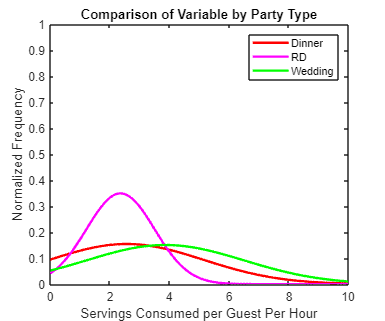

f3 = figure;
set(f3, 'Position', [1000,316,600,500])

ColorChoice_i = [1 0 0; 
    1 0 1; 
    0 1 0; 
    0 1 1; 
    .5 1 1; 
    1 .5 .5; 
    1 .5 1; 
    .5 .125 .5; 
    .25 .75 0];

ColorChoice = 1;
pos=1;
TypeErrors = [];

for i = 1:length(unique(DataSheet.Type)) % For the length of each type of event
    UniqueTypes = unique(DataSheet.Type); % Take the types
    CurrentType = UniqueTypes(i); % Pick one
    iData = DataSheet.Drinks_G_Hr(find(strcmpi(DataSheet.Type, CurrentType))); % Create a data set out of events of that type only
    if length(iData) < 2
        TypeErrors(pos,1) = append('Data for type "', CurrentType, '" are too few to generate even a guess.');
        pos = pos+1;
        continue
    end
    Var_i_mu = mean(iData); % Generate its mean
    Var_i_sigma = std(iData); % Standard deviation
    Var_i_x = 0:.05:10; % Paint it across these x's
    Var_i_y = normpdf(Var_i_x,   Var_i_mu,  Var_i_sigma); % Paint a normal curve above those x's of the data's distribution pattern
    CurrentLine = plot(Var_i_x,Var_i_y, 'DisplayName', CurrentType{1}); % Plot all that
    CurrentLine.LineWidth = 2;
    CurrentLine.Color = ColorChoice_i(ColorChoice,:);
    ColorChoice = ColorChoice + 1; % Before restarting, reset the color to a new one so the next line is different
   
 
    hold on
end
xlabel('Servings Consumed per Guest Per Hour')
ylabel('Normalized Frequency')
title('Comparison of Variable by Party Type')
ylim([0 1])
legend
hold off

#### Graphing Consumption at Evening vs Non-Evening Parties

The original datasheet has a column with a checkbox for "Evening", marking each party. That checkbox produces either "TRUE" or "FALSE" in the sheet. This variable is, hypothetically, most likely to show an extreme difference, most evening events are parties, most non-evening events are brief or formal. However, a high drink consumption at a morning memorial is not unseen.

f8 = figure;
set(f3, 'Position', [1000,316,600,500]);
hold on
% Keep in mind, these variable are composed of Drinks/Guest/Hour.

EveningEventIDX = find(DataSheet.Evening);
Evening = DataSheet.Drinks_G_Hr(EveningEventIDX);
NonEvening = DataSheet.Drinks_G_Hr(~EveningEventIDX);

Evening_mu = mean(Evening);
Evening_sigma = std(Evening);
Evening_x = linspace(0, 15); % Just give me a row of x values unto 15, to paint the curve along

Evening_x =          0    0.1515    0.3030    0.4545    0.6061    0.7576    0.9091    1.0606    1.2121    1.3636    1.5152    1.6667    1.8182    1.9697    2.1212    2.2727    2.4242    2.5758    2.7273    2.8788    3.0303    3.1818    3.3333    3.4848    3.6364    3.7879    3.9394    4.0909    4.2424    4.3939    4.5455    4.6970    4.8485    5.0000    5.1515    5.3030    5.4545    5.6061    5.7576    5.9091    6.0606    6.2121    6.3636    6.5152    6.6667    6.8182    6.9697    7.1212    7.2727    7.4242


Evening_y = normpdf(Evening_x,Evening_mu,Evening_sigma)

Evening_y =     0.0775    0.0845    0.0918    0.0992    0.1067    0.1142    0.1217    0.1291    0.1363    0.1432    0.1497    0.1558    0.1614    0.1664    0.1707    0.1743    0.1772    0.1793    0.1805    0.1809    0.1804    0.1791    0.1770    0.1740    0.1704    0.1660    0.1609    0.1553    0.1491    0.1426    0.1356    0.1284    0.1211    0.1136    0.1060    0.0985    0.0911    0.0839    0.0769    0.0701    0.0636    0.0575    0.0517    0.0462    0.0412    0.0365    0.0322    0.0283    0.0247    0.0215



NonEvening_mu = mean(NonEvening);
NonEvening_sigma = std(NonEvening);
NonEvening_x = linspace(0, 15); % Just give me a row of x values unto 15, to paint the curve along

NonEvening_x =          0    0.1515    0.3030    0.4545    0.6061    0.7576    0.9091    1.0606    1.2121    1.3636    1.5152    1.6667    1.8182    1.9697    2.1212    2.2727    2.4242    2.5758    2.7273    2.8788    3.0303    3.1818    3.3333    3.4848    3.6364    3.7879    3.9394    4.0909    4.2424    4.3939    4.5455    4.6970    4.8485    5.0000    5.1515    5.3030    5.4545    5.6061    5.7576    5.9091    6.0606    6.2121    6.3636    6.5152    6.6667    6.8182    6.9697    7.1212    7.2727    7.4242


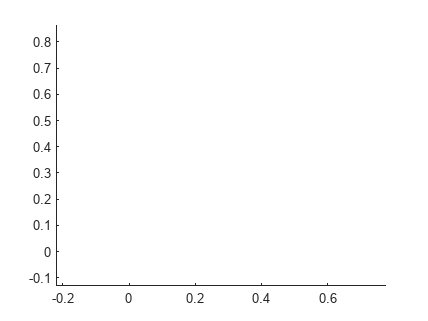

NonEvening_y = normpdf(NonEvening_x, NonEvening_mu,NonEvening_sigma);

plot()

hold off

### Running a Two-Way ANOVA Test on Comparisons

#### Type of Event

#### Evening versus Non-Evening

## Beer and Wine (BW) Events Versus Beer, Wine, and Liquor (BWL) Events

One factor which we would suspect predicts alcohol consumption is the selection offered by the bar. That selection is, itself, a measurement of many factors about the event. For instance, luncheons, or any event that isn't in the evening, is likely to not serve liquor. In addition, any event that chooses not to serve liquor is likely doing so because of a number of factors that imply that the guests shouldn't be--or shouldn't want or need to be--drinking as much. The star exception to this pattern is the "tailgate," where beer and wine is the most usual selection, yet consumption, as is shown above, can be quite high. The preponderance of tailgates in the full dataset, as opposed to, say, luncheons, is liable to have a decisive effect on the appearance of this graph.

This section splits events thanks to the "Selection" column of the Average Alcohol Consumption Rates sheet. This column uses a function to label that party as either "Limited" (only one type is offered) "Beer and Wine" or "Full" (beer, wine, and liquor offered). 

If the dataset does not contain enough instances of a certain event type to generate a reasonable curve, the curve is not drawn, and instead Figure 5 lists the event type as insufficiently recorded.

f4 = figure;
set(f4, 'Position', [3,6,950,397]) % Left-to-right, bottom-to-top, width, height

ServByGuestPerHour2_mu = mean(DataSheet.Drinks_G_Hr);
ServByGuestPerHour2_sigma = std(DataSheet.Drinks_G_Hr);
ServByGuestPerHour2_x = linspace(0, 10, 100);
ServByGuestPerHour2_y = normpdf(ServByGuestPerHour2_x, ServByGuestPerHour2_mu, ServByGuestPerHour2_sigma);
FullLine = plot(ServByGuestPerHour2_x, ServByGuestPerHour2_y, '-', 'HandleVisibility','on', 'Color',[.8 .8 .8],'DisplayName','Combined Data');

hold on

% BW_Data = DataSheet.Drinks_G_Hr(find(isnan(DataSheet.Liquor)));
% BWL_Data = DataSheet.Drinks_G_Hr(find(~isnan(DataSheet.Liquor)));

BW_Data = DataSheet.Drinks_G_Hr(find(strcmpi(DataSheet.Selection, 'B & W')));
BWL_Data = DataSheet.Drinks_G_Hr(find(strcmpi(DataSheet.Selection, 'Full')));

BW_mu = mean(BW_Data); % Generate its mean
BW_sigma = std(BW_Data); % Standard deviation
BW_x = 0:.05:10; % Paint it across these x's
BW_y = normpdf(BW_x,   BW_mu,  BW_sigma); % Paint a normal curve above those x's of the data's distribution pattern
BWLine = plot(BW_x,BW_y, '-r', 'HandleVisibility','on','DisplayName','Beer & Wine'); % Plot all that
BWLine.LineWidth = 1.3;
 
BWL_mu = mean(BWL_Data); % Generate its mean
BWL_sigma = std(BWL_Data); % Standard deviation
BWL_x = 0:.05:10; % Paint it across these x's
BWL_y = normpdf(BWL_x,   BWL_mu,  BWL_sigma); % Paint a normal curve above those x's of the data's distribution pattern
BWLLine = plot(BWL_x,BWL_y, '-b', 'HandleVisibility','on', 'DisplayName','Beer, Wine & Liquor'); % Plot all that
BWLLine.LineWidth = 1.3;
  
  
title('Comparison of Consumption by Bar Type');
legend;
ylim([0 1]);
box("on")


% Measurements of Dispersion for each

text(7,.38,['σ = ' num2str(BW_sigma)], 'Color','red', 'FontWeight','bold');
    
text(7,.35,['σ = ' num2str(BWL_sigma)], 'Color','blue','FontWeight','bold');

text(7,.41,['σ = ' num2str(ServByGuestPerHour2_sigma)], 'Color','black', 'FontWeight','bold');

% AD-Test values for the BW, BWL, and combined datasets

[h, BW_p] = adtest(BW_Data);
AD_BW_Pvalue = num2str(fix(BW_p*10000)/10000);
text(7,.38,['p = ' AD_BW_Pvalue], 'Color','red', 'FontWeight','bold');
    
[h, BWL_p] = adtest(BWL_Data);

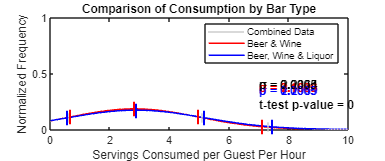

AD_BWL_Pvalue = num2str(fix(BWL_p*10000)/10000);
text(7,.35,['p = ' AD_BWL_Pvalue], 'Color','blue','FontWeight','bold');

text(7,.41,['p = ' AD_Pvalue], 'Color','black', 'FontWeight','bold');

xlabel('Servings Consumed per Guest Per Hour')
ylabel('Normalized Frequency')

% Let's spruce it up with some markings

% Tic mark at max and SDs

x_markers_Full = [ServByGuestPerHour2_mu-ServByGuestPerHour2_sigma*2 ServByGuestPerHour2_mu-ServByGuestPerHour2_sigma   ServByGuestPerHour2_mu   ServByGuestPerHour2_mu+ServByGuestPerHour2_sigma ServByGuestPerHour2_mu+ServByGuestPerHour2_sigma*2];
    y_markers_Full = interp1(ServByGuestPerHour2_x, ServByGuestPerHour2_y, x_markers_Full); % Given an X and Y dataset, where would the Y of this hypothetical X (not in the original dataset) be???
    plot(x_markers_Full, y_markers_Full, '|k','MarkerSize', 8, 'HandleVisibility', 'off','LineWidth', 1.3, 'Color',[.8 .8 .8])


    x_markers_BW = [BW_mu-BW_sigma*2 BW_mu-BW_sigma   BW_mu   BW_mu+BW_sigma BW_mu+BW_sigma*2];
    y_markers_BW = interp1(BW_x, BW_y, x_markers_BW);
    plot(x_markers_BW, y_markers_BW, '|r','MarkerSize', 12, 'HandleVisibility', 'off', 'LineWidth', 1.5)


    x_markers_BWL = [BWL_mu-BWL_sigma*2 BWL_mu-BWL_sigma   BWL_mu   BWL_mu+BWL_sigma BWL_mu+BWL_sigma*2];
    y_markers_BWL = interp1(BWL_x, BWL_y, x_markers_BWL);
    plot(x_markers_BWL, y_markers_BWL, '|b','MarkerSize', 12, 'HandleVisibility', 'off','LineWidth', 1.5)


xlim([0 10]);

hold off

% Now let's run a curve comparison on our two data sets, BW and BWL.
[h, p] = ttest2(BW_mu, BWL_mu, 'Vartype', 'unequal','Alpha',.01);
text(7, .23, ['t-test p-value = ' num2str(p)], 'FontWeight','bold');



f5 = figure;
f5_text = uicontrol('style', 'text');
f5.Position = [999,7,600,226];
f5_text.Position = [11,18,735,197];
f5_text.HorizontalAlignment = "left";
f5_text.FontSize = 14;

if ~isempty(TypeErrors)
    then f5_text.String = TypeErrors;
end

## Variations Throughout the Year

### Guest count throughout year

The company sees fierce fluctuations in the number of events in a given month. Busy seasons might see many events per week, while slower seasons may come to a complete standstill. Here, we can generate a curve representing the predicted fluctuations of guest counts over the months. According to employees, the company experiences two wedding seasons (corresponding to the periods of summer before and after the peak of heat), and a Christmas holiday party rush, followed by relative dead zones. Let's see if we can see this represented in the bar's data (keeping in mind that, in the grand scheme of things, events with bars are a large but not complete subsection of all the events; however, the generated curve is in principle perfectly applicable to the *bar department's* guest fluctuations).

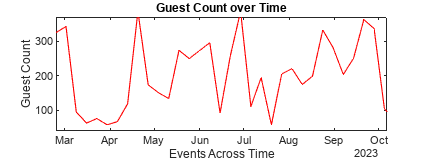

% Sort the dates in ascending order
[Sorted_Dates, idx] = sort(DataSheet.Date, 'ascend');

% Use the indices returned by sort to rearrange the values
DateSorted_Guests = DataSheet.Guests(idx);


f6 = figure;
f6.Position = [999,7,600,226];
plot(Sorted_Dates, DateSorted_Guests, 'r-');
title('Guest Count over Time')
ylabel('Guest Count')
xlabel('Events Across Time')

### Beer Inventory Flow by the Month

This section calculates the amount of each type of beer offerered that was consumed each month. When divided by the guests in that month, we get an approximation of how much of each type of beer is consumed per guest that month. By knowing the prospective guest count of that month, the user can then plan out a par of each type of beer to have on hand, going into that month. (Across years, the guest count will potentially rise, and this growth rate can be measured and factored into this)

f7 = figure;

% % Group the data by month using the grpstats function
[~,month] = datevec(DataSheet.Date)

month =      2
     3
     3
     3
     3
     3
     4
     4
     4
     4


DataSheet.Tropicalia

ans =   242.6667
   96.0400
   31.0333
   47.0400
   28.3733
   24.3600
   43.7733
   61.0867
  144.4800
   64.9600


% [MonthGroup,gn] = findgroups(month);
% 
% Tropicalia_MonthGrouped = grpstats(DataSheet.Tropicalia,MonthGroup,);
% Michelob_MonthGrouped = grpstats(DataSheet.Michelob,MonthGroup);
% PeachState_MonthGrouped = grpstats(DataSheet.PeachState,MonthGroup);
% Selzter_MonthGrouped = grpstats(DataSheet.Selzter,MonthGroup);
% Bud_MonthGrouped = grpstats(DataSheet.BudLight,MonthGroup);
% Recreational_MonthGrouped = grpstats(DataSheet.Recreational,MonthGroup);
% 
% bar(Recreational_MonthGrouped)

for i = 1:12
       EventsForMonth(i, 2) = DataSheet(find(month == i))
end

Error using  () 
Subscripting into a table using one subscript (as in t(i)) is not supported. Specify a row subscript and a variable subscript, as in t(rows,vars). To
select variables, use t(:,i) or for one variable t.(i). To select rows, use t(i,:).


   % for j = {'Tropicalia' 'Michelob' 'PeachState' 'Selzter' 'BudLight' 'Recreational'}